%新方法-分区域拟合

%标定
squareSize = 1.500000e+00;  % in units of 'millimeters'
imds=imageDatastore("9.19");
imageFileName=imds.Files

imageFileName = 3×1 cell 数组
    {'C:\Users\12630\Desktop\图像处理\相机标定\9.19\20240919-141004-896.bmp'}
    {'C:\Users\12630\Desktop\图像处理\相机标定\9.19\20240919-141124-240.bmp'}
    {'C:\Users\12630\Desktop\图像处理\相机标定\9.19\20240919-141219-620.bmp'}


% Detect calibration pattern in images
[imagePoints, boardSize] = detectCheckerboardPoints(imageFileName);

%展示第一张图片及检测出的角点
i=1;
I=imread(imageFileName{i});
J = insertText(I,imagePoints(:,:,i),1:size(imagePoints(:,:,i),1));
% J = insertMarker(J,imagePoints,'o','MarkerColor','red','Size',5);
imshow(J);
title(sprintf('Detected a %d x %d Checkerboard',boardSize));

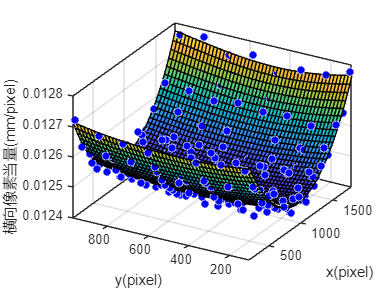

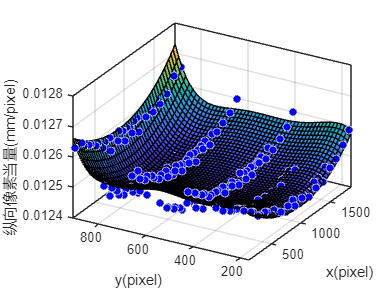

%计算像素当量分布，并用二次曲面拟合
ft = 'poly45';
opts = fitoptions;
opts.Normalize="on";
[sftx,sfty]=calculate_sft(imageFileName,squareSize,ft = ft,opts = opts);


% % 计算原点
% [U,V]=calculate_origin(sftx,sfty);
% origin=[double(U),double(V)];
origin=[960,540];

%计算平均校准精度
NumPatterns=length(imageFileName);
worldPoints = generateCheckerboardPoints(boardSize, squareSize);
error=zeros(length(imagePoints),NumPatterns);
for i=1:NumPatterns
    newWorldPoints= coordinate_transformation(origin,imagePoints(:,:,i),sftx,sfty);
    tform = fitgeotform2d(newWorldPoints,worldPoints,"similarity");
    newWorldPoints=tform.R*newWorldPoints'+tform.Translation';
    newWorldPoints=newWorldPoints';
    for j=1:length(newWorldPoints)
        error(j,i)=norm(worldPoints(j,:)-newWorldPoints(j,:));
    end
end
MeanCalibrationError=mean(error)

MeanCalibrationError =     0.0023    0.0023    0.0026


std(error)

ans =     0.0011    0.0011    0.0013


[im,worldPoints]=undistort_image(I,sftx,sfty,nan_replace=0);

[sftx,sfty]=calculate_undistort_sft(imageFileName,squareSize,worldPoints);

%对所有实际标准块图像进行测量
imds=imageDatastore("测量\5(1).29");
imageFileNames=imds.Files;
dists=zeros(length(imageFileNames),3);
for k=1:length(imageFileNames)
    RGB=imread(imageFileNames{k});
    RGB=undistort_image2(RGB,worldPoints);
    gray=rgb2gray(RGB);
    gray_edge=edge(gray,"canny",0.15);
    
    % 根据边缘特性，去除标准块内部的干扰边缘
    [row,col]=size(gray_edge);
    [P_left,P_right]=calculate_fitline(gray,gray_edge);
    
    y=linspace(1,row,5);
    x_r=(y-P_right(2))./P_right(1);
    x_l=(y-P_left(2))./P_left(1);
    for i=2:4
        [x_ver,y_ver]=find_vertical_ponit(P_right(1),P_right(2),x_l(i),y(i));
        image2Point=[x_ver,y_ver;x_l(i),y(i)];
        world2Point=coordinate_transformation(origin,image2Point,sftx,sfty);
        dist1(i-1)=norm(world2Point(1,:)-world2Point(2,:));
    end
    dists(k,:)=dist1;
end
dists=change_order(dists)

RGB=imread("测量\5(1).29\10mm-右.bmp");
imshow(RGB)
RGB=undistort_image2(RGB,worldPoints);
gray=rgb2gray(RGB);
gray_edge=edge(gray,"canny",0.15);
imshow(gray_edge)

% 根据边缘特性，去除标准块内部的干扰边缘
[row,col]=size(gray_edge);
edge_I=false(row,col);
for i=10:row-10
    for j=10:col
        if gray_edge(i,j)==1
            edge_I(i,j)=1;
            break;
        end
    end
end
l_xy=subpixel_points2(gray,edge_I);
[P_left,l_xy_new]=polyfit_L(l_xy,5)
imshow(edge_I)
edge_I=false(row,col);
for i=10:row-10
    for j=col-10:-1:1
        if gray_edge(i,j)==1
            edge_I(i,j)=1;
            break;
        end
    end
end
r_xy=subpixel_points2(gray,edge_I);
[P_right,xy_new]=polyfit_Para_L(r_xy,P_left(1),5)

imshow(gray)
hold on
plot(l_xy(:,1),l_xy(:,2),".")
plot(r_xy(:,1),r_xy(:,2),".")
y=linspace(1,row,5);
x_r=(y-P_right(2))./P_right(1);
x_l=(y-P_left(2))./P_left(1);
origin=[960,540];
for i=2:4
    [x_ver,y_ver]=find_vertical_ponit(P_right(1),P_right(2),x_l(i),y(i));
    plot([x_ver,x_l(i)],[y_ver,y(i)],LineWidth=2)
    image2Point=[x_ver,y_ver;x_l(i),y(i)];
    world2Point=coordinate_transformation(origin,image2Point,sftx,sfty);
    dist1(i-1)=norm(world2Point(1,:)-world2Point(2,:));
    text(mean([x_ver,x_l(i)])-10,mean([y_ver,y(i)])+10,num2str(dist1(i-1)))
end
plot(x_l,y)
plot(x_r,y)
hold off

